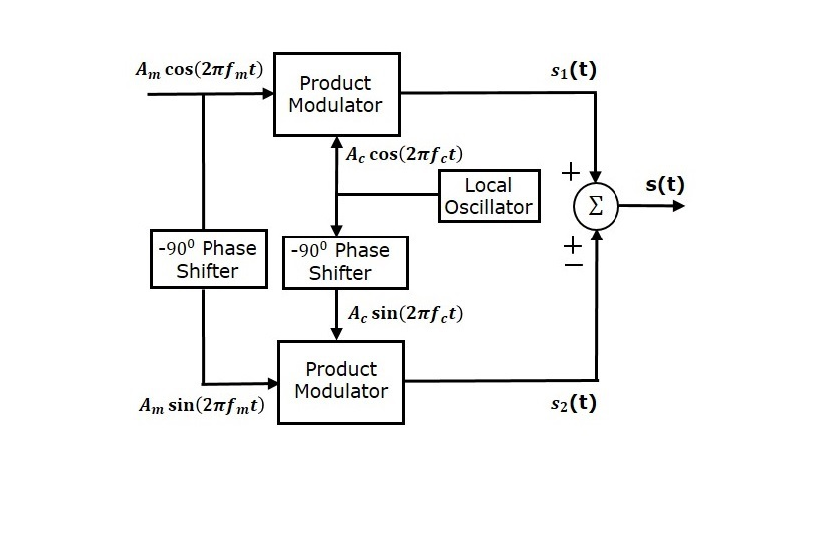

close all
clear all
clc

imshow("C:\Users\ganes\Documents\MATLAB\ssb.jpg")

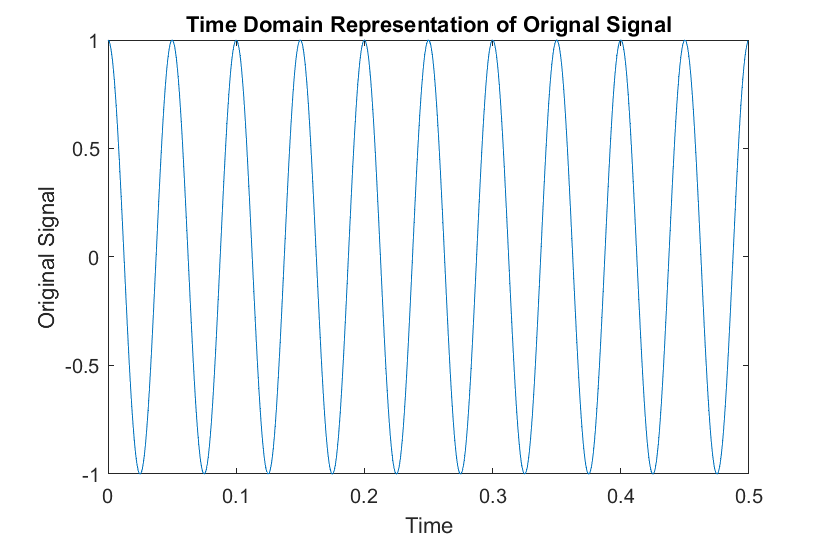

N = 1024;
fs = 2048;
ts = 1/fs;
t=(0:N-1)/fs;
fc = 600; 
fm = 20;
Am = 1;
Ac = 2;

m = Am*cos(2*pi*fm*t); %Message
mh = Am*cos((2*pi*fm*t)-pi/2); %Hilbert transform of the message signal


sbu = m.*Ac.*cos(2*pi*fc*t) - mh.*Ac.*sin(2*pi*fc*t); %Expression for USB SSB
sbl = m.*Ac.*cos(2*pi*fc*t) + mh.*Ac.*sin(2*pi*fc*t); %Expression for LSB SSB

SBU = 2/N*abs(fft(sbu)); %Fourier Transform of USB SSB
SBL = 2/N*abs(fft(sbl)); %Fourier Transform of LSB SSB

SNR=10; % signal noise ratio
ns=awgn(m,SNR,'measured'); nsh=awgn(mh,SNR,'measured'); % adding white gaussian noise


sbu_N = ns.*Ac.*cos(2*pi*fc*t) - nsh.*Ac.*sin(2*pi*fc*t); %Expression for USB SSB
sbl_N = ns.*Ac.*cos(2*pi*fc*t) + nsh.*Ac.*sin(2*pi*fc*t); %Expression for LSB SSB

SBU_N = 2/N*abs(fft(sbu_N)); %Fourier Transform of USB SSB
SBL_N = 2/N*abs(fft(sbl_N)); %Fourier Transform of LSB SSB

freq = fs * (0 : N/2) / N;

figure(1);
plot(t,m);
title('Time Domain Representation of Orignal Signal');
xlabel('Time'); ylabel('Original Signal');

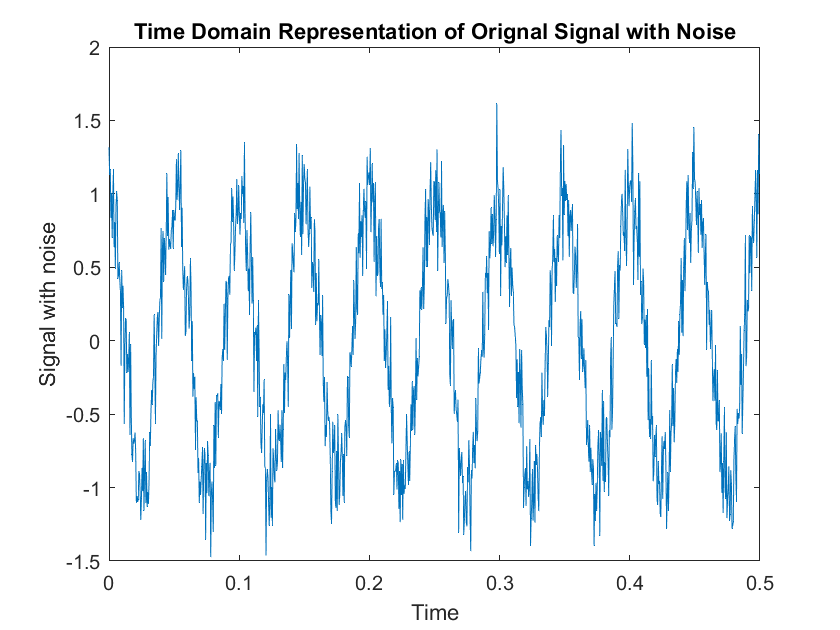


figure(2);
plot(t,ns) % signal with noise
title('Time Domain Representation of Orignal Signal with Noise');
xlabel('Time'); ylabel('Signal with noise');

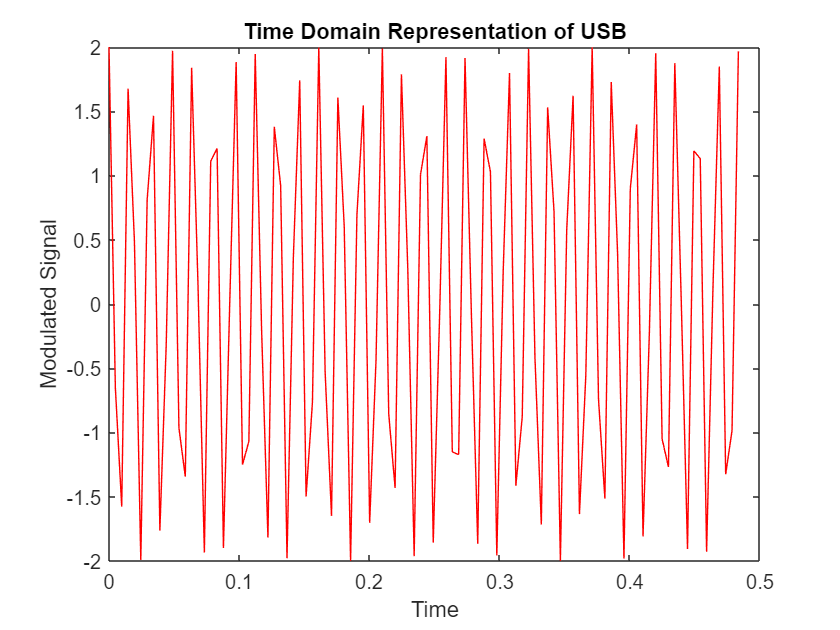


figure(3);
plot(10*t(1:100),sbu(1:100),'r');%Time Domain Plot of USB SSB
title('Time Domain Representation of USB');
xlabel('Time'); ylabel('Modulated Signal');

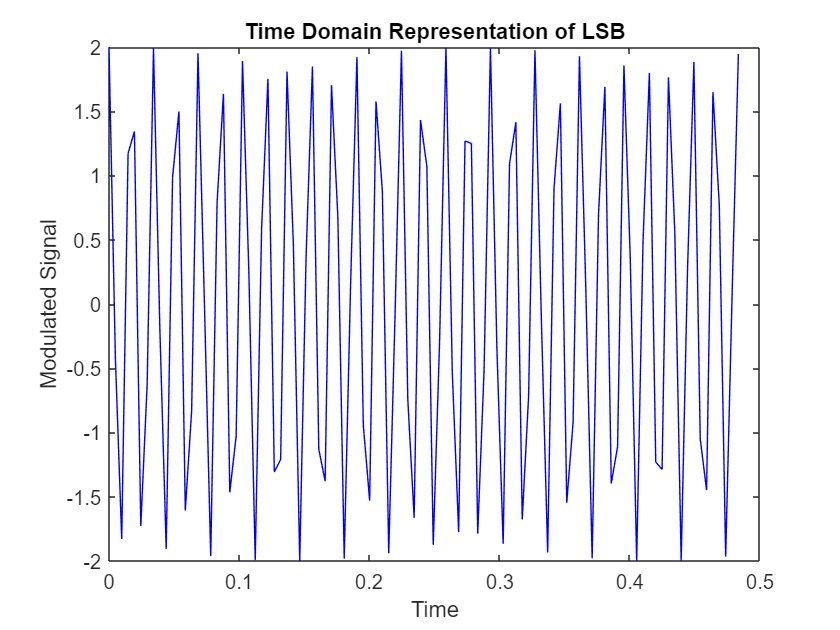


figure(4);
plot(10*t(1:100),sbl(1:100),'b');%Time Domain Plot of LSB SSB
title('Time Domain Representation of LSB');
xlabel('Time'); ylabel('Modulated Signal');

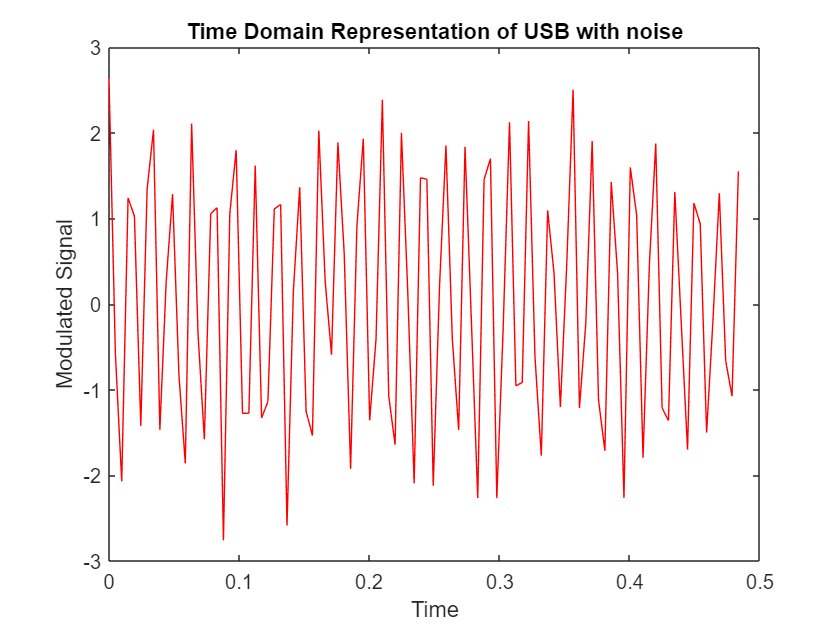


figure(5);
plot(10*t(1:100),sbu_N(1:100),'r');%Time Domain Plot of USB SSB
title('Time Domain Representation of USB with noise');
xlabel('Time'); ylabel('Modulated Signal');

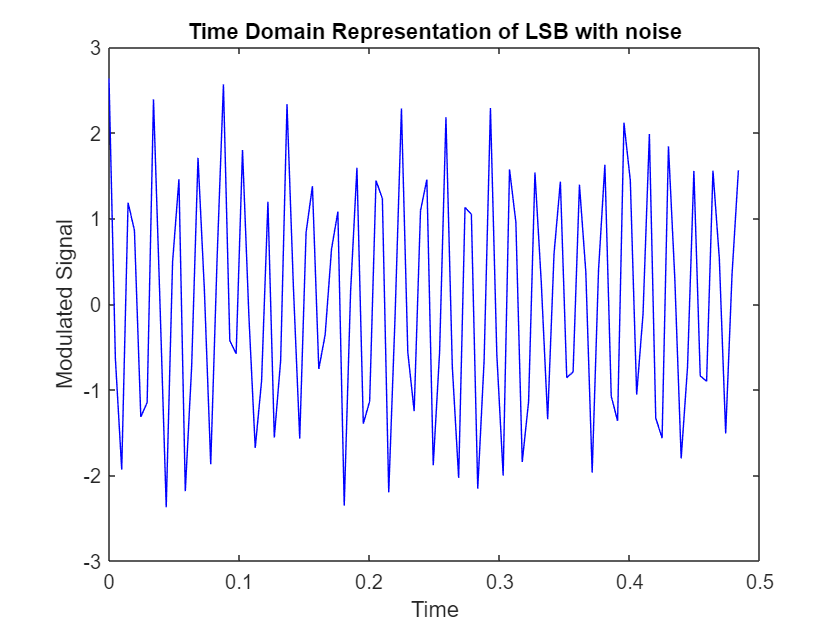


figure(6);
plot(10*t(1:100),sbl_N(1:100),'b');%Time Domain Plot of LSB SSB
title('Time Domain Representation of LSB with noise');
xlabel('Time'); ylabel('Modulated Signal');

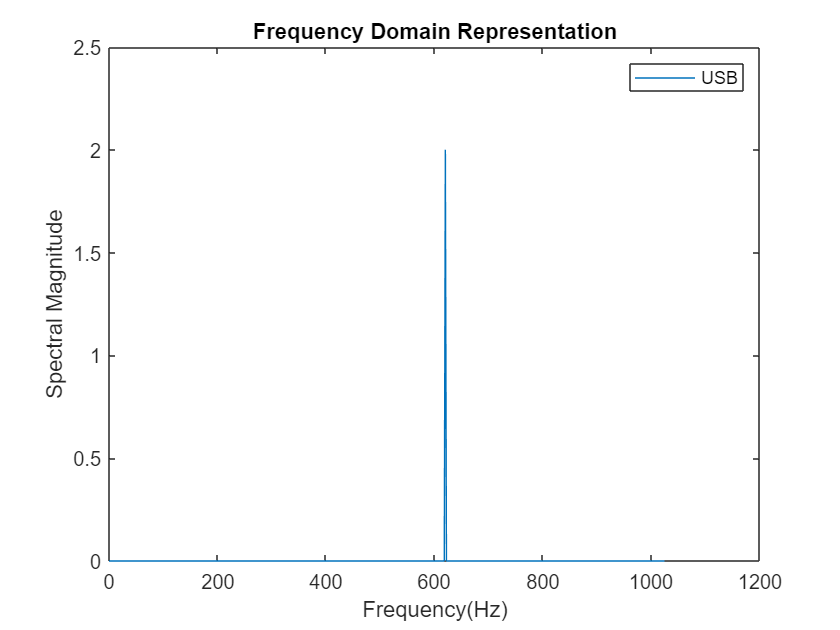


figure(7);
plot(freq,SBU(1:N/2+1))
title('Frequency Domain Representation');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB');

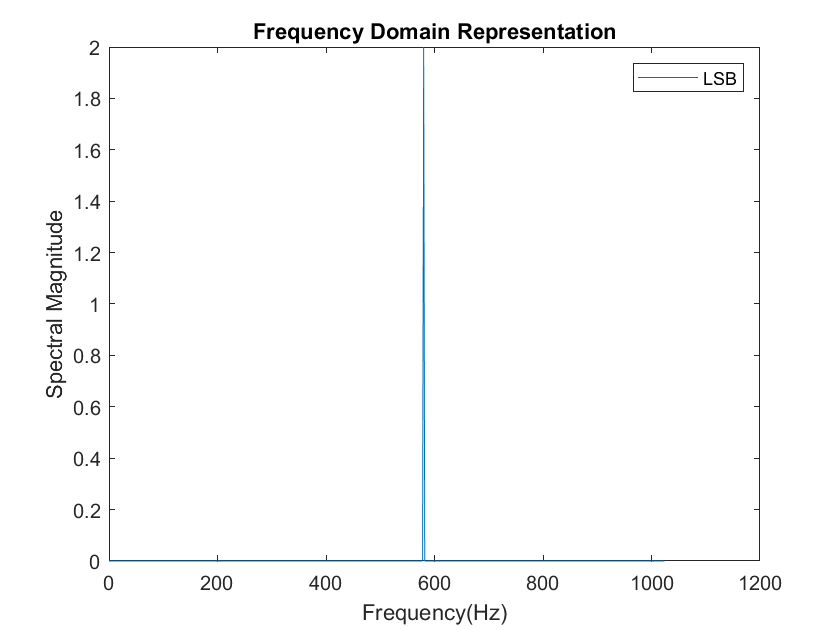


figure(8);
plot(freq,SBL(1:N/2+1)); %Frequency domain plot
title('Frequency Domain Representation');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('LSB');

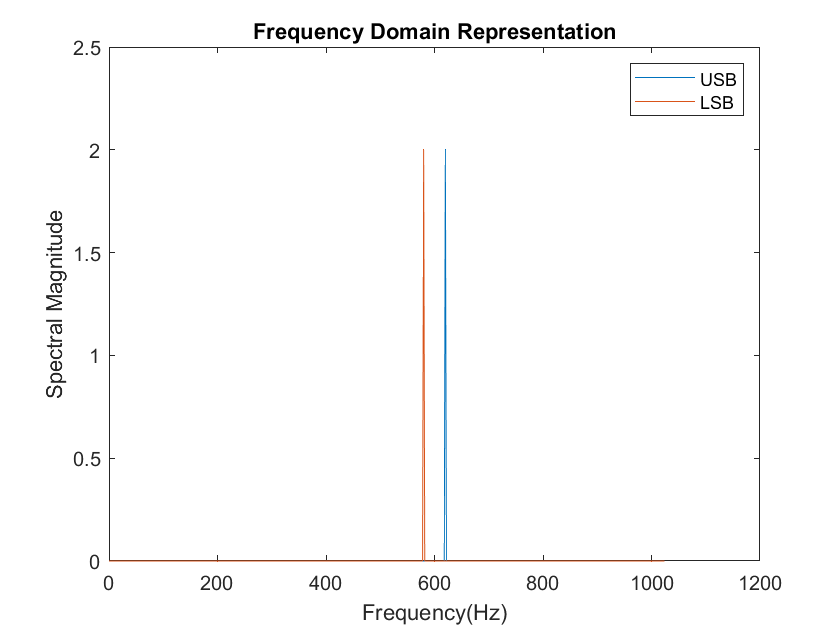


figure(9);
plot(freq,SBU(1:N/2+1),freq,SBL(1:N/2+1));
title('Frequency Domain Representation');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB','LSB');

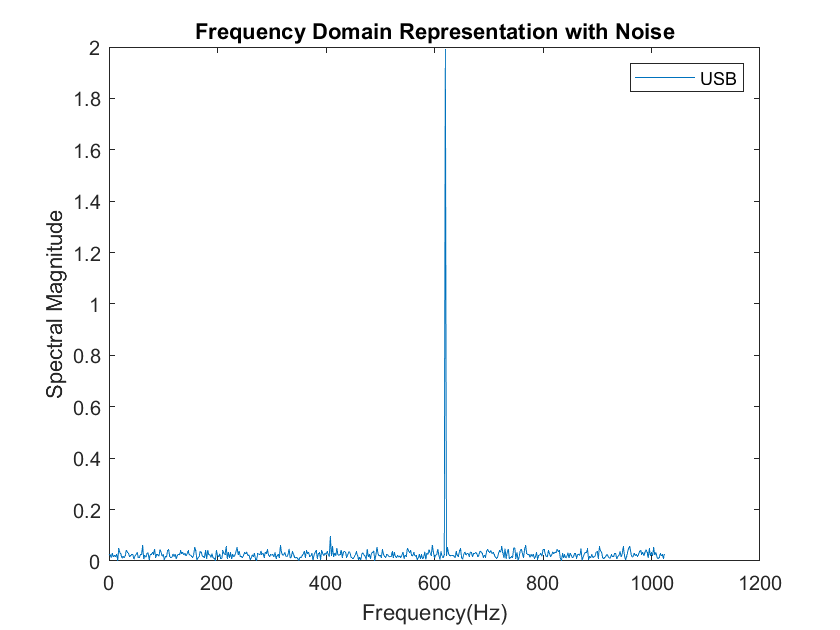


figure(10);
plot(freq,SBU_N(1:N/2+1))
title('Frequency Domain Representation with Noise');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB');

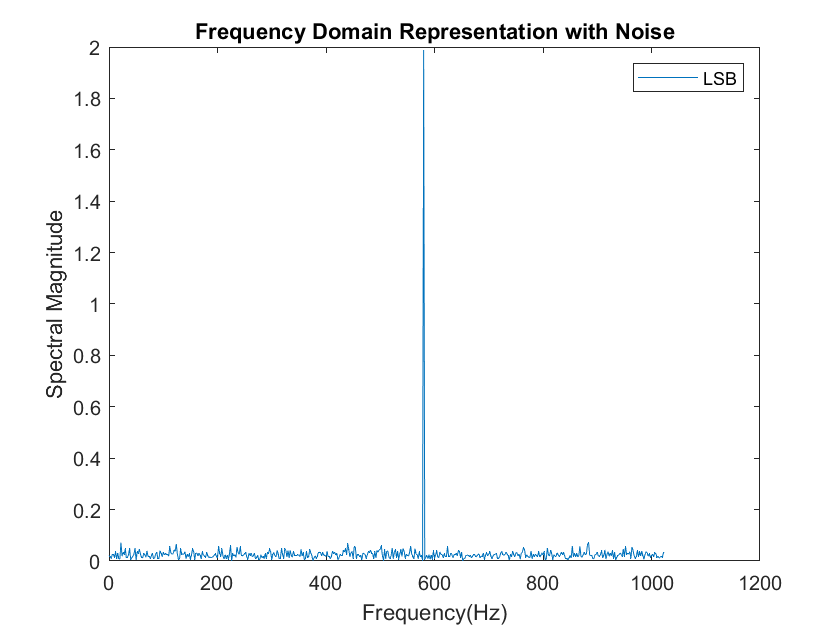


figure(11);
plot(freq,SBL_N(1:N/2+1)); %Frequency domain plot
title('Frequency Domain Representation with Noise');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('LSB');

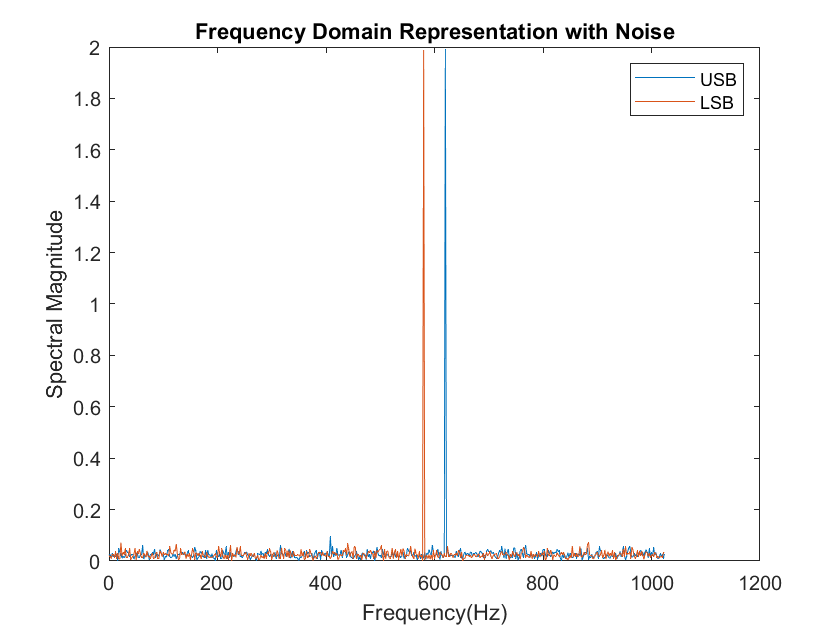


figure(12);
plot(freq,SBU_N(1:N/2+1),freq,SBL_N(1:N/2+1));
title('Frequency Domain Representation with Noise');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB','LSB');

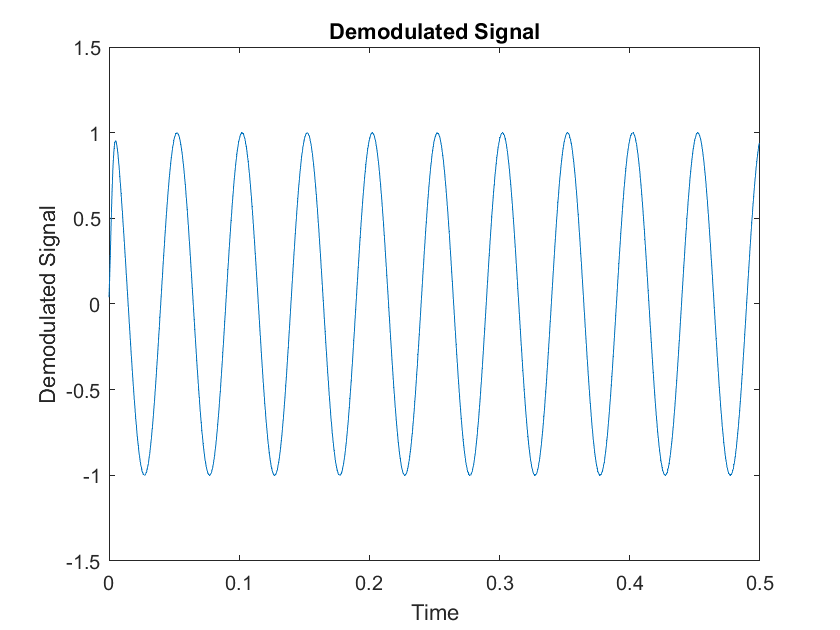



%Demodulation:
md=sbu.*cos(2*pi*fc*t);
[b,a]=butter(2,0.1,'low');
mf=filter(b,a,md);
figure(13);
plot(t,mf)
title('Demodulated Signal');
xlabel('Time'); ylabel('Demodulated Signal');